# **Mimic Joint Resolution**

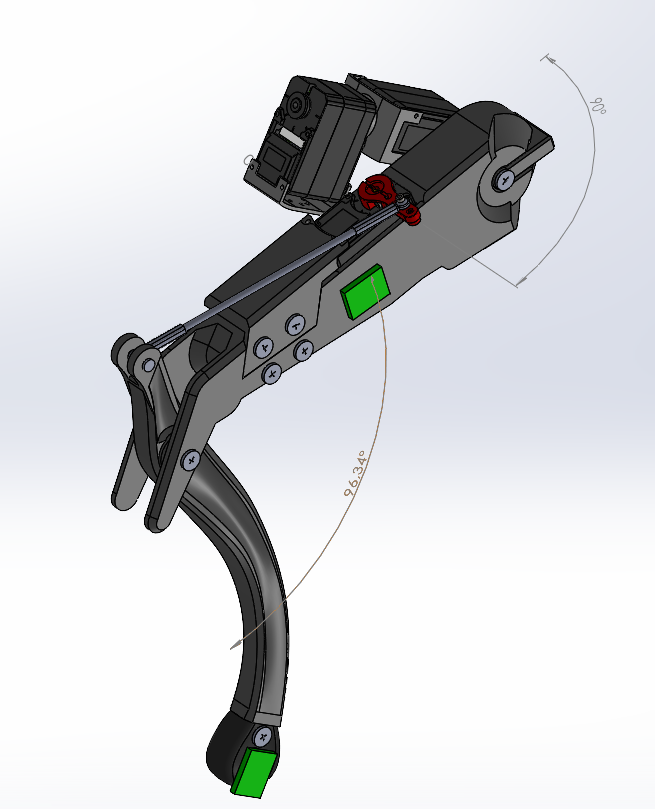

% Data
% Data
ArTh = [90; 0; 45; 90; 135; 180];
ShTh = [96.31; 117.76; 111.74; 96.32; 78.92; 70.63];

% Convert to radians
ArTh_rad = deg2rad(ArTh);
ShTh_rad = deg2rad(ShTh);

% Standard linear regression (y = ax + b)
coeffs = polyfit(ArTh_rad, ShTh_rad, 1);
ShTh_pred = coeffs(1) * ArTh_rad + coeffs(2);

% Print equation
fprintf('Linear regression: ShTh = %.4f * ArTh + %.4f\n', coeffs(1), coeffs(2))

Linear regression: ShTh = -0.2824 * ArTh + 2.1065


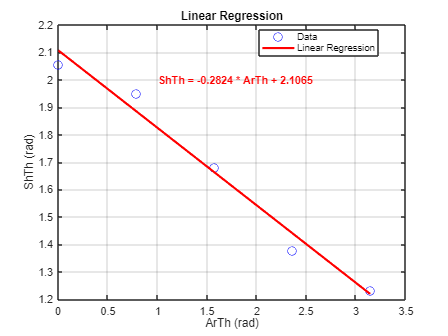


% Plot
figure
plot(ArTh_rad, ShTh_rad, 'bo', 'MarkerSize', 8, 'DisplayName', 'Data')
hold on
plot(ArTh_rad, ShTh_pred, 'r-', 'LineWidth', 2, 'DisplayName', 'Linear Regression')
xlabel('ArTh (rad)')
ylabel('ShTh (rad)')
title('Linear Regression')
grid on
legend('Location', 'best')

% Add equation to plot
text(1, 2, sprintf('ShTh = %.4f * ArTh + %.4f', coeffs(1), coeffs(2)), ...
   'Color', 'red', 'FontWeight', 'bold', 'FontSize', 10)

**Forward Kinematics**

%% ========================== FORWARD KINEMATICS ==========================
function [P0, P1, P2, P3, Pe] = T_0_e(q1, q2, q3, dxL1, dzL1, dxL2, dxL3)
    % FK matching your corrected model

    T_0_1 = [cos(q1),  sin(q1), 0, 0;
            -sin(q1),  cos(q1), 0, 0;
             0      ,  0      , 1, 0;
             0      ,  0      , 0, 1];

    T_1_2 = [ 0       , 0      , 1      , -dxL1;
             -sin(q2), cos(q2), 0      , 0;
              cos(q2), sin(q2), 0      , dzL1;
              0      , 0      , 0      , 1];

    T_2_3 = [cos(q3),  sin(q3), 0, dxL2;
            -sin(q3),  cos(q3), 0, 0;
             0     ,  0      , 1, 0;
             0     ,  0      , 0, 1];

    T_3_e = eye(4); T_3_e(1,4) = dxL3;

    T01 = T_0_1;
    T02 = T01 * T_1_2;
    T03 = T02 * T_2_3;
    T0e = T03 * T_3_e;

    P0 = [0; 0; 0];
    P1 = T01(1:3, 4);
    P2 = T02(1:3, 4);
    P3 = T03(1:3, 4);
    Pe = T0e(1:3, 4);
end

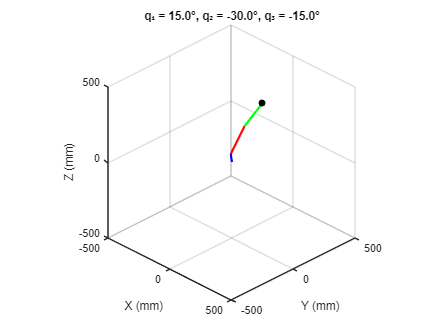

function leg_fk_simulation()
    % Main simulation of the forward kinematics (FK) of the quadruped front-right leg (LegFR)
    close all; clc;

    % Call the animation function
    animate_leg_trajectory();
end

%% ========================== ANIMATION FUNCTION ==========================
function animate_leg_trajectory()
    % Geometric constants of the leg (in mm)
    dxL1 = 14.4;
    dzL1 = 45.9;
    dxL2 = 181.39;
    dxL3 = 170.42;

    % Create figure and 3D environment
    figure;
    axis equal;
    grid on;
    xlabel('X (mm)');
    ylabel('Y (mm)');
    zlabel('Z (mm)');
    view(45, 30);
    xlim([-500, 500]); ylim([-500, 500]); zlim([-500, 500]);
    hold on;

    % Animate over 100 steps with varying joint angles
    for i = 1:100
        q1 = deg2rad(15);  % Fixed base rotation
        q2 = deg2rad(-30 + 10 * sin(i * 2 * pi / 100));  % Oscillating joint
        q3 = deg2rad(-30 + 15 * cos(i * 2 * pi / 100));  % Oscillating joint

        % Get joint positions using forward kinematics
        [P0, P1, P2, P3, Pe] = T_0_e(q1, q2, q3, dxL1, dzL1, dxL2, dxL3);

        cla;

        % Plot the leg links
        plot3([P0(1), P1(1)], [P0(2), P1(2)], [P0(3), P1(3)], 'k-', 'LineWidth', 2); % Base
        plot3([P1(1), P2(1)], [P1(2), P2(2)], [P1(3), P2(3)], 'b-', 'LineWidth', 2); % Link1
        plot3([P2(1), P3(1)], [P2(2), P3(2)], [P2(3), P3(3)], 'r-', 'LineWidth', 2); % Link2
        plot3([P3(1), Pe(1)], [P3(2), Pe(2)], [P3(3), Pe(3)], 'g-', 'LineWidth', 2); % Foot

        % Mark the end-effector (foot)
        plot3(Pe(1), Pe(2), Pe(3), 'ko', 'MarkerFaceColor', 'k');

        % Display current angles
        title(sprintf('q₁ = %.1f°, q₂ = %.1f°, q₃ = %.1f°', ...
            rad2deg(q1), rad2deg(q2), rad2deg(q3)));

        pause(0.03);
    end
end

% Call the main function to run simulation
leg_fk_simulation();

Best configuration found:
q1 = 26.00°, q2 = -20.00°, q3 = -90.00°, error = 128.78 mm


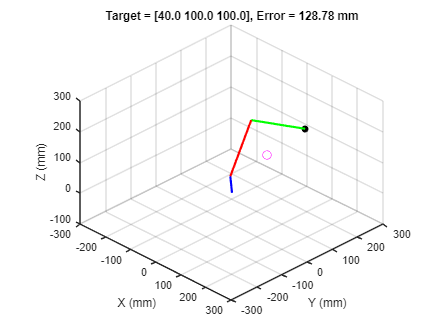

function leg_ik_gridsearch_simulation()
    close all; clc;

    % ------------------ Geometrie de la jambe (en mm) ------------------
    dxL1 = 14.4; dzL1 = 45.9; dxL2 = 181.39; dxL3 = 170.42;

    % ------------------ Cible désirée ------------------
    target = [40; 100; 100];  % modifie ici ton point cible

    % ------------------ Grille d'angles (en rad) ------------------
    q1_vals = deg2rad(-60:2:60);
    q2_vals = deg2rad(-60:2:60);
    q3_vals = deg2rad(-90:2:0);

    % ------------------ Recherche de la meilleure config ------------------
    min_err = inf;
    best_q = [0 0 0];
    best_Pe = [0;0;0];

    for q1 = q1_vals
        for q2 = q2_vals
            for q3 = q3_vals
                [~, ~, ~, ~, Pe] = T_0_e(q1, q2, q3, dxL1, dzL1, dxL2, dxL3);
                err = norm(Pe - target);
                if err < min_err
                    min_err = err;
                    best_q = [q1 q2 q3];
                    best_Pe = Pe;
                end
            end
        end
    end

    % ------------------ Affichage résultat ------------------
    fprintf("Best configuration found:\n");
    fprintf("q1 = %.2f°, q2 = %.2f°, q3 = %.2f°, error = %.2f mm\n", ...
        rad2deg(best_q(1)), rad2deg(best_q(2)), rad2deg(best_q(3)), min_err);

    % ------------------ Tracé ------------------
    figure;
    axis equal; grid on; hold on;
    xlabel('X (mm)'); ylabel('Y (mm)'); zlabel('Z (mm)');
    view(45, 30); xlim([-300 300]); ylim([-300 300]); zlim([-100 300]);

    [P0, P1, P2, P3, Pe] = T_0_e(best_q(1), best_q(2), best_q(3), dxL1, dzL1, dxL2, dxL3);
    plot3([P0(1) P1(1)], [P0(2) P1(2)], [P0(3) P1(3)], 'k-', 'LineWidth', 2);
    plot3([P1(1) P2(1)], [P1(2) P2(2)], [P1(3) P2(3)], 'b-', 'LineWidth', 2);
    plot3([P2(1) P3(1)], [P2(2) P3(2)], [P2(3) P3(3)], 'r-', 'LineWidth', 2);
    plot3([P3(1) Pe(1)], [P3(2) Pe(2)], [P3(3) Pe(3)], 'g-', 'LineWidth', 2);
    plot3(Pe(1), Pe(2), Pe(3), 'ko', 'MarkerFaceColor', 'k');
    plot3(target(1), target(2), target(3), 'mo', 'MarkerSize', 8);
    title(sprintf("Target = [%.1f %.1f %.1f], Error = %.2f mm", ...
        target(1), target(2), target(3), min_err));
end

leg_ik_gridsearch_simulation()

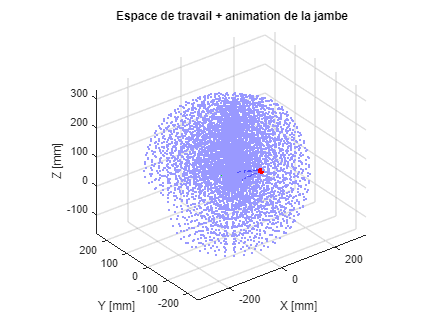

% Constantes géométriques (en mm)
dxL1 = 14.4;
dzL1 = 45.9;
dxL2 = 181.39;
dxL3 = 170.42;

% Plages d'angles articulaires
q1_range = linspace(-pi/2, pi/2, 20);
q2_range = linspace(-pi/4, pi/2, 20);
q3_range = linspace(-pi/2, pi/2, 20);

% Génération du nuage atteignable
reachable = [];
for q1 = q1_range
    for q2 = q2_range
        for q3 = q3_range
            q23 = q2 + q3;
            x = -dxL1 * cos(q1) - dxL2 * sin(q1)*sin(q2) + dxL3 * sin(q1)*sin(q23);
            y = -dxL1 * sin(q1) - dxL2 * cos(q1)*sin(q2) + dxL3 * cos(q1)*sin(q23);
            z = dzL1 + dxL2 * cos(q2) - dxL3 * cos(q23);
            reachable(end+1,:) = [x y z];
        end
    end
end

% Préparation de la figure
figure;
hold on; grid on; axis equal;
xlabel('X [mm]'); ylabel('Y [mm]'); zlabel('Z [mm]');
title('Espace de travail + animation de la jambe');
view(3);

% Nuage de points atteignables (bleu clair)
scatter3(reachable(:,1), reachable(:,2), reachable(:,3), 5, [0.6 0.6 1], 'filled');

% Animation : jambe mobile dans l’espace
for q1 = linspace(-pi/3, pi/3, 15)
    for q2 = linspace(0, pi/2, 10)
        for q3 = linspace(-pi/2, pi/4, 10)

            q23 = q2 + q3;

            % Base
            P0 = [0 0 0];
            P1 = [-dxL1*cos(q1), -dxL1*sin(q1), 0];
            P2 = P1 + [-dxL2*sin(q1)*sin(q2), -dxL2*cos(q1)*sin(q2), dxL2*cos(q2)];
            P3 = P2 + [dxL3*sin(q1)*sin(q23), dxL3*cos(q1)*sin(q23), -dxL3*cos(q23)];

            % Effacer ancienne jambe
            h = findobj('Tag','leg_line');
            delete(h);

            % Tracer segments articulés (barres bleues transparentes)
            plot3([P0(1), P1(1)], [P0(2), P1(2)], [P0(3), P1(3)], '-', ...
                'LineWidth', 1.5, 'Color', [0 0 1 0.3], 'Tag','leg_line');
            plot3([P1(1), P2(1)], [P1(2), P2(2)], [P1(3), P2(3)], '-', ...
                'LineWidth', 2, 'Color', [0 0 1 0.4], 'Tag','leg_line');
            plot3([P2(1), P3(1)], [P2(2), P3(2)], [P2(3), P3(3)], '-', ...
                'LineWidth', 2, 'Color', [0 0 1 0.5], 'Tag','leg_line');

            % Tracer articulations
            plot3(P1(1), P1(2), P1(3), 'ko', 'MarkerFaceColor','k', 'Tag','leg_line');
            plot3(P2(1), P2(2), P2(3), 'ro', 'MarkerFaceColor','r', 'Tag','leg_line');
            plot3(P3(1), P3(2), P3(3), 'go', 'MarkerFaceColor','g', 'Tag','leg_line');

            pause(0.03);
        end
    end
end

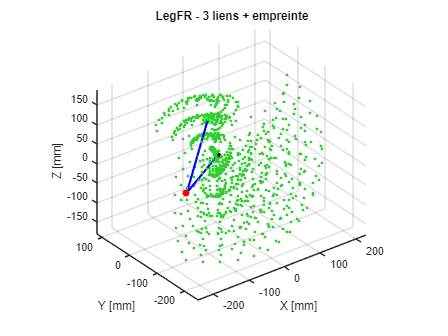

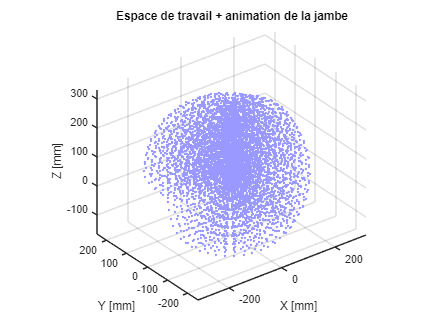


% Constantes géométriques (en mm)
dxL1 = 14.4;
dzL1 = 45.9;
dxL2 = 181.39;
dxL3 = 170.42;

% Plages d'angles articulaires
q1_range = linspace(-pi/3, pi/3, 10);
q2_range = linspace(0, pi/2, 10);
q3_range = linspace(-pi/2, pi/4, 10);

% Préparation de la figure
figure;
hold on; grid on; axis equal;
xlabel('X [mm]'); ylabel('Y [mm]'); zlabel('Z [mm]');
title('LegFR - 3 liens + empreinte');
view(3);

% Initialisation de l'empreinte
foot_trace = [];

% Boucle d’animation
for q1 = q1_range
    for q2 = q2_range
        for q3 = q3_range

            q23 = q2 + q3;

            % Point 0 : base
            P0 = [0, 0, 0];

            % Point 1 : après le lien L1 (rotation horizontale)
            P1 = [-dxL1*cos(q1), -dxL1*sin(q1), 0];

            % Point 2 : après le lien cuisse
            P2 = P1 + [-dxL2*sin(q1)*sin(q2), ...
                       -dxL2*cos(q1)*sin(q2), ...
                        dxL2*cos(q2)];

            % Point 3 : après le lien tibia (pied)
            P3 = P2 + [dxL3*sin(q1)*sin(q23), ...
                       dxL3*cos(q1)*sin(q23), ...
                      -dxL3*cos(q23)];

            % Ajouter l’empreinte verte (persistante)
            foot_trace(end+1,:) = P3;
            plot3(P3(1), P3(2), P3(3), '.', 'Color', [0.2 0.8 0.2], 'MarkerSize', 8);

            % Effacer l’ancienne structure
            h = findobj('Tag','leg_line');
            delete(h);

            % Lien 1 : Base → articulation 1
            plot3([P0(1), P1(1)], [P0(2), P1(2)], [P0(3), P1(3)], '-', ...
                'Color', [0 0 1 0.2], 'LineWidth', 2, 'Tag','leg_line');

            % Lien 2 : articulation 1 → articulation 2 (cuissard)
            plot3([P1(1), P2(1)], [P1(2), P2(2)], [P1(3), P2(3)], '-', ...
                'Color', [0 0 1 0.4], 'LineWidth', 2, 'Tag','leg_line');

            % Lien 3 : articulation 2 → pied (tibia)
            plot3([P2(1), P3(1)], [P2(2), P3(2)], [P2(3), P3(3)], '-', ...
                'Color', [0 0 1 0.6], 'LineWidth', 2, 'Tag','leg_line');

            % Articulations
            plot3(P1(1), P1(2), P1(3), 'ko', 'MarkerFaceColor', 'k', 'Tag','leg_line');
            plot3(P2(1), P2(2), P2(3), 'ro', 'MarkerFaceColor', 'r', 'Tag','leg_line');
            plot3(P3(1), P3(2), P3(3), 'go', 'MarkerFaceColor', 'g', 'Tag','leg_line');

            pause(0.03);
        end
    end
end

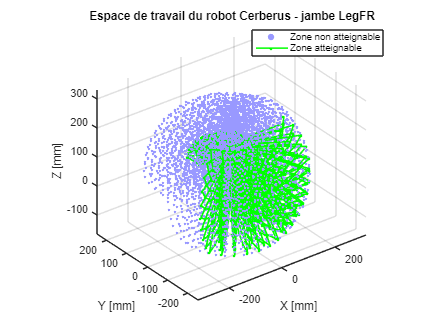

% --- Constantes géométriques (en mm)
dxL1 = 14.4;
dzL1 = 45.9;
dxL2 = 181.39;
dxL3 = 170.42;

% --- Portée maximale approximative
L_total = dxL2 + dxL3;

% --- Grilles d'angles
q1_all = linspace(-pi/2, pi/2, 20);
q2_all = linspace(-pi/4, pi/2, 20);
q3_all = linspace(-pi/2, pi/2, 20);

% Initialisation
reachable = [];
unreachable = [];
foot_trace = [];

% --- Génération du nuage atteignable/inatteignable
for q1 = q1_all
    for q2 = q2_all
        for q3 = q3_all
            q23 = q2 + q3;
            x = -dxL1 * cos(q1) - dxL2 * sin(q1)*sin(q2) + dxL3 * sin(q1)*sin(q23);
            y = -dxL1 * sin(q1) - dxL2 * cos(q1)*sin(q2) + dxL3 * cos(q1)*sin(q23);
            z = dzL1 + dxL2 * cos(q2) - dxL3 * cos(q23);
            d = sqrt(x^2 + y^2 + (z - dzL1)^2);
            if d <= L_total * 1.1
                reachable(end+1,:) = [x y z];
            else
                unreachable(end+1,:) = [x y z];
            end
        end
    end
end

% --- Génération de la trace réelle du pied (via itérations)
q1_range = linspace(-pi/3, pi/3, 10);
q2_range = linspace(0, pi/2, 10);
q3_range = linspace(-pi/2, pi/4, 10);
for q1 = q1_range
    for q2 = q2_range
        for q3 = q3_range
            q23 = q2 + q3;
            x = -dxL1 * cos(q1) - dxL2 * sin(q1)*sin(q2) + dxL3 * sin(q1)*sin(q23);
            y = -dxL1 * sin(q1) - dxL2 * cos(q1)*sin(q2) + dxL3 * cos(q1)*sin(q23);
            z = dzL1 + dxL2 * cos(q2) - dxL3 * cos(q23);
            foot_trace(end+1,:) = [x y z];
        end
    end
end

% --- Affichage 3D final
figure;
hold on; grid on; axis equal;
xlabel('X [mm]'); ylabel('Y [mm]'); zlabel('Z [mm]');
title('Espace de travail du robot Cerberus - jambe LegFR');
view(3);

% Nuage atteignable
if ~isempty(reachable)
    scatter3(reachable(:,1), reachable(:,2), reachable(:,3), 5, [0.6 0.6 1], 'filled');
end

% Nuage inatteignable
if ~isempty(unreachable)
    scatter3(unreachable(:,1), unreachable(:,2), unreachable(:,3), 5, [1 0.6 0.6], 'filled');
end

% Trajectoire réelle du pied
if ~isempty(foot_trace)
    plot3(foot_trace(:,1), foot_trace(:,2), foot_trace(:,3), 'g.-', 'LineWidth', 1.5);
end

legend('Zone non atteignable', 'Zone atteignable', 'Trajectoire réelle du pied', 'Location', 'best');

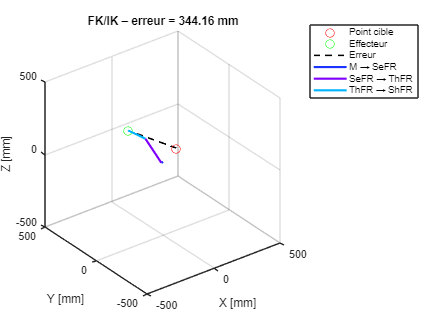

% --- Constantes géométriques (mm)
dxL1 = 14.4;
dzL1 = 45.9;
dxL2 = 181.39;
dxL3 = 170.42;

% --- Trajectoire cible
t = linspace(0, 2*pi, 150);
X_target = 100 * cos(t);
Y_target = 100 * sin(t);
Z_target = 60 + 30 * sin(2*t);

% --- Initialisation figure
figure;
axis equal; grid on; hold on;
xlabel('X [mm]'); ylabel('Y [mm]'); zlabel('Z [mm]');
xlim([-500 500]); ylim([-500 500]); zlim([-500 500]);
view(3);
title('Jambe LegFR : Suivi de point cible avec FK/IK');

% --- Objets graphiques
target_dot = plot3(NaN, NaN, NaN, 'ro', 'MarkerSize', 8, 'DisplayName', 'Point cible');
effector_dot = plot3(NaN, NaN, NaN, 'go', 'MarkerSize', 8, 'DisplayName', 'Effecteur');
error_line = plot3([NaN NaN], [NaN NaN], [NaN NaN], 'k--', 'LineWidth', 1.5, 'DisplayName', 'Erreur');
link1 = plot3([NaN NaN], [NaN NaN], [NaN NaN], '-', 'Color', [0.1 0.2 1], 'LineWidth', 2, 'DisplayName', 'M → SeFR');
link2 = plot3([NaN NaN], [NaN NaN], [NaN NaN], '-', 'Color', [0.5 0 1], 'LineWidth', 2, 'DisplayName', 'SeFR → ThFR');
link3 = plot3([NaN NaN], [NaN NaN], [NaN NaN], '-', 'Color', [0 0.7 1], 'LineWidth', 2, 'DisplayName', 'ThFR → ShFR');

legend('show');

% --- Animation avec affichage de l'erreur
for k = 1:length(t)
    % Cible
    xe = X_target(k); ye = Y_target(k); ze = Z_target(k);

    % IK analytique
    q1 = atan2(ye, xe);
    Hxy = sqrt(xe^2 + ye^2);
    x1 = Hxy + dxL1;
    z1 = ze - dzL1;
    D = (x1^2 + z1^2 - dxL2^2 - dxL3^2) / (2 * dxL2 * dxL3);
    D = min(max(D, -1), 1);
    q3 = acos(D);
    q2 = atan2(z1, x1) - atan2(dxL3 * sin(q3), dxL2 + dxL3 * cos(q3));
    q23 = q2 + q3;

    % FK - positions
    P0 = [0 0 0];
    P1 = [-dxL1*cos(q1), -dxL1*sin(q1), 0];
    P2 = P1 + [-dxL2*sin(q1)*sin(q2), -dxL2*cos(q1)*sin(q2), dxL2*cos(q2)];
    P3 = P2 + [dxL3*sin(q1)*sin(q23), dxL3*cos(q1)*sin(q23), -dxL3*cos(q23)];

    % Calcul de l’erreur (distance entre cible et point atteint)
    err = norm(P3 - [xe, ye, ze]);

    % Mise à jour graphique
    set(target_dot, 'XData', xe, 'YData', ye, 'ZData', ze);
    set(effector_dot, 'XData', P3(1), 'YData', P3(2), 'ZData', P3(3));
    set(error_line, 'XData', [xe P3(1)], 'YData', [ye P3(2)], 'ZData', [ze P3(3)]);
    set(link1, 'XData', [P0(1) P1(1)], 'YData', [P0(2) P1(2)], 'ZData', [P0(3) P1(3)]);
    set(link2, 'XData', [P1(1) P2(1)], 'YData', [P1(2) P2(2)], 'ZData', [P1(3) P2(3)]);
    set(link3, 'XData', [P2(1) P3(1)], 'YData', [P2(2) P3(2)], 'ZData', [P2(3) P3(3)]);

    % Mettre à jour le titre avec la valeur d’erreur
    title(sprintf('FK/IK – erreur = %.2f mm', err));

    drawnow;
end

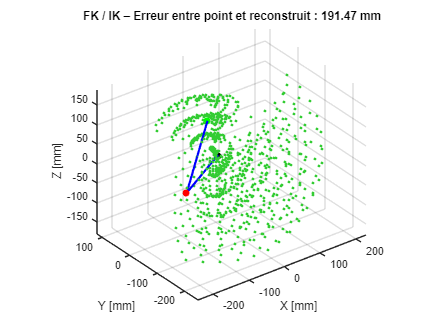

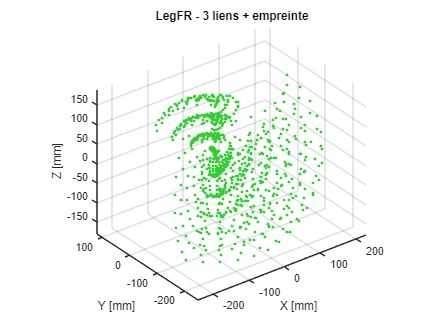

⚠️ IK FAUSSE: err = 360.13 mm
⚠️ IK FAUSSE: err = 397.82 mm
⚠️ IK FAUSSE: err = 420.70 mm
⚠️ IK FAUSSE: err = 425.80 mm
⚠️ IK FAUSSE: err = 412.16 mm
⚠️ IK FAUSSE: err = 380.27 mm
⚠️ IK FAUSSE: err = 375.97 mm
⚠️ IK FAUSSE: err = 414.72 mm
⚠️ IK FAUSSE: err = 441.19 mm
⚠️ IK FAUSSE: err = 452.84 mm
⚠️ IK FAUSSE: err = 413.98 mm
⚠️ IK FAUSSE: err = 438.37 mm
⚠️ IK FAUSSE: err = 447.23 mm
⚠️ IK FAUSSE: err = 439.12 mm
⚠️ IK FAUSSE: err = 415.00 mm
⚠️ IK FAUSSE: err = 378.43 mm
⚠️ IK FAUSSE: err = 373.00 mm
⚠️ IK FAUSSE: err = 413.89 mm
⚠️ IK FAUSSE: err = 432.97 mm
⚠️ IK FAUSSE: err = 433.10 mm
⚠️ IK FAUSSE: err = 451.43 mm
⚠️ IK FAUSSE: err = 463.26 mm
⚠️ IK FAUSSE: err = 459.73 mm
⚠️ IK FAUSSE: err = 441.04 mm
⚠️ IK FAUSSE: err = 410.17 mm
⚠️ IK FAUSSE: err = 373.33 mm
⚠️ IK FAUSSE: err = 369.29 mm
⚠️ IK FAUSSE: err = 410.36 mm
⚠️ IK FAUSSE: err = 418.21 mm
⚠️ IK FAUSSE: err = 403.82 mm
⚠️ IK FAUSSE: err = 472.27 mm
⚠️ IK FAUSSE: err = 472.73 mm
⚠️ IK FAUSSE: err = 458.82 mm
⚠️ IK FAUS

% --- Constantes géométriques (en mm)
dxL1 = 14.4;
dzL1 = 45.9;
dxL2 = 181.39;
dxL3 = 170.42;

% --- Plages des angles articulaires
q1_range = linspace(-pi/3, pi/3, 10);
q2_range = linspace(0, pi/2, 10);
q3_range = linspace(-pi/2, pi/4, 10);

% --- Préparation de la figure
figure;
hold on; grid on; axis equal;
xlabel('X [mm]'); ylabel('Y [mm]'); zlabel('Z [mm]');
title('LegFR - Animation 3D + Empreinte + Vérification IK');
view(3);

% --- Initialisation de l’empreinte
foot_trace = [];

% --- Boucle sur les combinaisons d’angles
for q1 = q1_range
    for q2 = q2_range
        for q3 = q3_range

            q23 = q2 + q3;

            % FK - Positions des points clés
            P0 = [0, 0, 0];
            P1 = [-dxL1*cos(q1), -dxL1*sin(q1), 0];
            P2 = P1 + [-dxL2*sin(q1)*sin(q2), -dxL2*cos(q1)*sin(q2), dxL2*cos(q2)];
            P3 = P2 + [dxL3*sin(q1)*sin(q23), dxL3*cos(q1)*sin(q23), -dxL3*cos(q23)];

            % Stocker l’empreinte
            foot_trace(end+1,:) = P3;
            plot3(P3(1), P3(2), P3(3), '.', 'Color', [0.2 0.8 0.2], 'MarkerSize', 8);

            % Effacer l’ancienne jambe
            delete(findobj('Tag','leg_line'));

            % Afficher la structure de la jambe
            plot3([P0(1) P1(1)], [P0(2) P1(2)], [P0(3) P1(3)], '-', ...
                'Color', [0 0 1 0.2], 'LineWidth', 2, 'Tag','leg_line'); % Lien 1
            plot3([P1(1) P2(1)], [P1(2) P2(2)], [P1(3) P2(3)], '-', ...
                'Color', [0 0 1 0.4], 'LineWidth', 2, 'Tag','leg_line'); % Lien 2
            plot3([P2(1) P3(1)], [P2(2) P3(2)], [P2(3) P3(3)], '-', ...
                'Color', [0 0 1 0.6], 'LineWidth', 2, 'Tag','leg_line'); % Lien 3

            % Afficher les articulations
            plot3(P1(1), P1(2), P1(3), 'ko', 'MarkerFaceColor', 'k', 'Tag','leg_line');
            plot3(P2(1), P2(2), P2(3), 'ro', 'MarkerFaceColor', 'r', 'Tag','leg_line');
            plot3(P3(1), P3(2), P3(3), 'go', 'MarkerFaceColor', 'g', 'Tag','leg_line');

            % --- Vérification de l’IK (point inverse → angles → point reconstruit)
            % Inverse Kinematics
            xe = P3(1); ye = P3(2); ze = P3(3);
            q1_ik = atan2(ye, xe);
            Hxy = sqrt(xe^2 + ye^2);
            x1_ik = Hxy + dxL1;
            z1_ik = ze - dzL1;
            D = (x1_ik^2 + z1_ik^2 - dxL2^2 - dxL3^2) / (2 * dxL2 * dxL3);
            D = min(max(D, -1), 1);
            q3_ik = acos(D);
            q2_ik = atan2(z1_ik, x1_ik) - atan2(dxL3*sin(q3_ik), dxL2 + dxL3*cos(q3_ik));

            % FK reconstruit à partir de l’IK
            q23_ik = q2_ik + q3_ik;
            P1_ik = [-dxL1*cos(q1_ik), -dxL1*sin(q1_ik), 0];
            P2_ik = P1_ik + [-dxL2*sin(q1_ik)*sin(q2_ik), -dxL2*cos(q1_ik)*sin(q2_ik), dxL2*cos(q2_ik)];
            P3_ik = P2_ik + [dxL3*sin(q1_ik)*sin(q23_ik), dxL3*cos(q1_ik)*sin(q23_ik), -dxL3*cos(q23_ik)];

            % Afficher erreur si > seuil
            err = norm(P3_ik - P3);
            if err > 1e-1
                fprintf("⚠️ IK FAUSSE: err = %.2f mm\n", err);
            end

            % Affichage de l’erreur dans le titre
            title(sprintf('FK / IK – Erreur entre point et reconstruit : %.2f mm', err));

            pause(0.02);
        end
    end
end

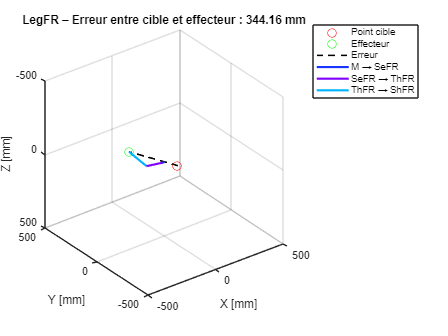


% --- Constantes géométriques (mm)
dxL1 = 14.4;
dzL1 = 45.9;
dxL2 = 181.39;
dxL3 = 170.42;

% --- Trajectoire cible
t = linspace(0, 2*pi, 150);
X_target = 100 * cos(t);
Y_target = 100 * sin(t);
Z_target = 60 + 30 * sin(2*t);

% --- Préparer la figure
figure;
hold on; grid on; axis equal;
xlabel('X [mm]'); ylabel('Y [mm]'); zlabel('Z [mm]');
xlim([-500 500]); ylim([-500 500]); zlim([-500 500]);
view(3);
set(gca, 'ZDir', 'reverse');
title('LegFR - FK/IK avec erreur');

% Objets graphiques persistants
target_dot = plot3(NaN, NaN, NaN, 'ro', 'MarkerSize', 8, 'DisplayName', 'Point cible');
effector_dot = plot3(NaN, NaN, NaN, 'go', 'MarkerSize', 8, 'DisplayName', 'Effecteur');
error_line = plot3([NaN NaN], [NaN NaN], [NaN NaN], 'k--', 'LineWidth', 1.5, 'DisplayName', 'Erreur');
link1 = plot3([NaN NaN], [NaN NaN], [NaN NaN], '-', 'Color', [0.1 0.2 1], 'LineWidth', 2, 'DisplayName', 'M → SeFR');
link2 = plot3([NaN NaN], [NaN NaN], [NaN NaN], '-', 'Color', [0.5 0 1], 'LineWidth', 2, 'DisplayName', 'SeFR → ThFR');
link3 = plot3([NaN NaN], [NaN NaN], [NaN NaN], '-', 'Color', [0 0.7 1], 'LineWidth', 2, 'DisplayName', 'ThFR → ShFR');

legend('show');

% --- Boucle principale
for k = 1:length(t)
    % Cible
    xe = X_target(k);
    ye = Y_target(k);
    ze = Z_target(k);

    % --- IK analytique
    q1 = atan2(ye, xe);
    Hxy = sqrt(xe^2 + ye^2);
    x1 = Hxy + dxL1;
    z1 = ze - dzL1;

    D = (x1^2 + z1^2 - dxL2^2 - dxL3^2) / (2 * dxL2 * dxL3);
    D = min(max(D, -1), 1);  % sécurité acos
    q3 = acos(D);
    q2 = atan2(z1, x1) - atan2(dxL3 * sin(q3), dxL2 + dxL3 * cos(q3));
    q23 = q2 + q3;

    % --- FK reconstruction
    P0 = [0 0 0];
    P1 = [-dxL1*cos(q1), -dxL1*sin(q1), 0];
    P2 = P1 + [-dxL2*sin(q1)*sin(q2), -dxL2*cos(q1)*sin(q2), dxL2*cos(q2)];
    P3 = P2 + [dxL3*sin(q1)*sin(q23), dxL3*cos(q1)*sin(q23), -dxL3*cos(q23)];

    % --- Affichage
    set(target_dot, 'XData', xe, 'YData', ye, 'ZData', ze);
    set(effector_dot, 'XData', P3(1), 'YData', P3(2), 'ZData', P3(3));
    set(error_line, 'XData', [xe P3(1)], 'YData', [ye P3(2)], 'ZData', [ze P3(3)]);
    set(link1, 'XData', [P0(1) P1(1)], 'YData', [P0(2) P1(2)], 'ZData', [P0(3) P1(3)]);
    set(link2, 'XData', [P1(1) P2(1)], 'YData', [P1(2) P2(2)], 'ZData', [P1(3) P2(3)]);
    set(link3, 'XData', [P2(1) P3(1)], 'YData', [P2(2) P3(2)], 'ZData', [P2(3) P3(3)]);

    % --- Erreur (affichée dans le titre)
    err = norm([xe, ye, ze] - P3);
    title(sprintf('LegFR – Erreur entre cible et effecteur : %.2f mm', err));

    drawnow;
end